# 4/1/2016 - Exploring the response timing 

See how high the voltages are in the channels that shouldn't be 

From Jenny -

Added tanks to look at for stim issues. ReactionTime-24: set to +10000 (open); -25: set to 0; -26: set to -10,000 (ground). (Jeneva Cronin)

% read in the converted file

uiimport



stim_info = Stim.info;
stim = Stim.data;

data = Wave.data;
data_info = Wave.info;

    fs_data = data_info.SamplingRateHz;
    fs_stim = stim_info.SamplingRateHz;

Sing_info = Sing.info;
Sing = Sing.data;

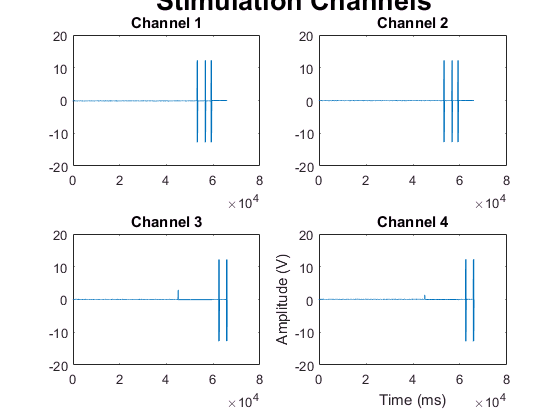

ans =   Axes (Stimulation Channels) with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1000 0.1000 0.8500 0.8500]
            Units: 'normalized'

  Show all properties


figure
hold on
for i = 1:size(stim,2)
    
    t = (1:length(stim))/fs_stim;
    subplot(2,2,i)
    plot(t*1e3,stim(:,i))
    title(sprintf('Channel %d',i))
    
    
end


xlabel('Time (ms)')
ylabel('Amplitude (V)')

subtitle('Stimulation Channels')

%% Sing looks like the wave to be delivered, with amplitude in uA

%Another attempt to dissect things

timeOfStim = find(Sing1Mask>0);

differenceTimeOfStim = diff(timeOfStim);
distBetween = find(differenceTimeOfStim>1);
sampleInd = timeOfStim(distBetween);

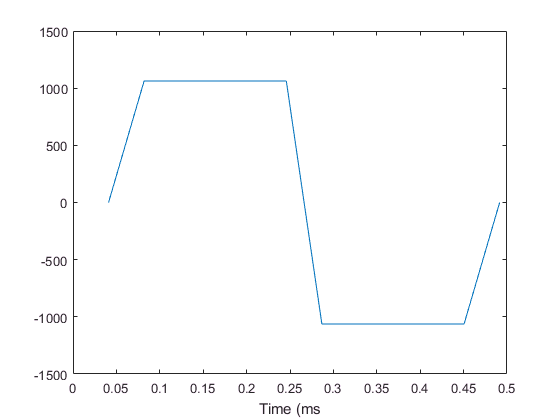


% build a burst table with the timing of stimuli
bursts = [];

Sing1 = Sing(:,1);
fs_sing = Sing_info.SamplingRateHz;

samplesOfPulse = round(2*fs_stim/1e3);



% trying something like A_BuildStimTables from BetaStim


Sing1Mask = Sing1~=0;
dmode = diff([0 Sing1Mask' 0 ]);


dmode(end-1) = dmode(end);


bursts(2,:) = find(dmode==1);
bursts(3,:) = find(dmode==-1);

% change bursts to be the first ones through the end. Something funny about the last one

bursts = bursts(:,1:end-1);

stims = squeeze(getEpochSignal(Sing1,(bursts(2,:)-1),(bursts(3,:))+1));
t = (1:size(stims,1))/fs_sing;
t = t*1e3;
figure
plot(t,stims)
xlabel('Time (ms');

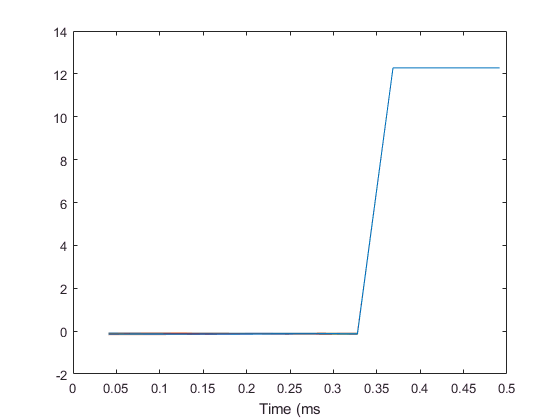


%% Plot stims with info from above

stim1 = stim(:,1);
stim1Epoched = squeeze(getEpochSignal(stim1,(bursts(2,:)-1),(bursts(3,:))+1));
t = (1:size(stim1Epoched,1))/fs_stim;
t = t*1e3;
figure
plot(t,stim1Epoched)
xlabel('Time (ms');


% hold on
%
% plot(t,stims)

delay = round(0.3277*fs_stim/1e3);

%% extract data
stimTimes = bursts(2,:)-1+delay;
presamps = round(0.025 * fs_data); % pre time in sec
postsamps = round(0.30 * fs_data); % post time in sec, % modified DJC to look at up to 300 ms after



fac = fs_stim/fs_data;

sts = round(stimTimes / fac);
